Set up parameters

disp('Parameter Setting')

Parameter Setting


gap_y=1/20

gap_y = 0.0500

aspt_ratio = 1.8

aspt_ratio = 1.8000

nuc_thres = 0.6

nuc_thres = 0.6000

gap_x = gap_y/aspt_ratio;

Plot Hu Heat Map

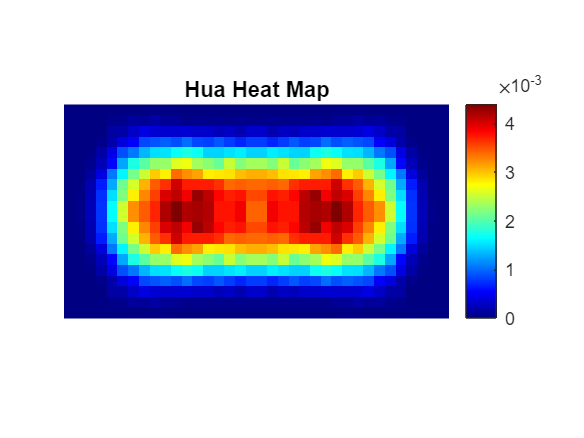

try
    for i=1:size(Result_cat)
        if Result_cat(i,1)>0
            Result_cat(i,1)=-Result_cat(i,1);
        end
        if Result_cat(i,2)>0
            Result_cat(i,2)=-Result_cat(i,2);
        end
    end
    Result_cat3=[Result_cat(:,1) -Result_cat(:,2)];
    Result_cat4=[-Result_cat(:,1) -Result_cat(:,2)];
    Result_cat5=[-Result_cat(:,1) Result_cat(:,2)];
    Result_cat_sym=[Result_cat(:,[1 2]);Result_cat3;Result_cat4;Result_cat5];
    clear Result_cat3 Result_cat4 Result_cat5 i
    
    Hu_sym = Result_cat_sym;
    clear Result_cat_sym Result_cat
catch
    if exist('Hu_sym','var') ~= 1
        disp('load Hua heat map raw data')
    end
end
% Plot original heat map of HUa
test = histcounts2(Hu_sym(:,1),Hu_sym(:,2),'XBinEdges',-0.5:gap_x:0.5,'YBinEdges',-0.5:gap_y:0.5);
test=test/(sum(sum(test)));
figure
imagesc(test.')
axis equal
colormap(gca,'jet');
colorbar;
shape_map=size(test);
xlim([0.5 shape_map(1)+0.5])
ylim([0.5 shape_map(2)+0.5])
axis off
title('Hua Heat Map')

Nucleoid Boundary and volume of nucleoid and projected region

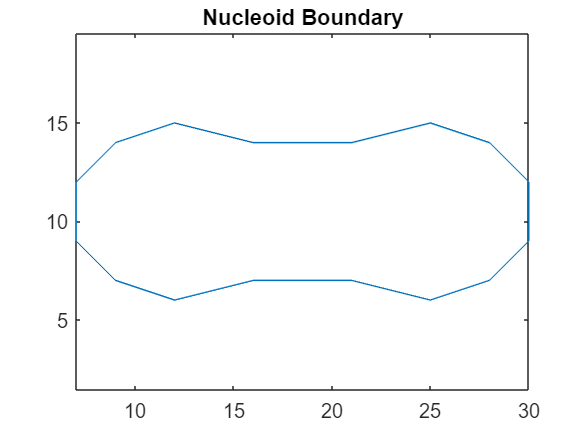

thres = max(max(test))*nuc_thres;
sel_ind = test>thres;
see = test;
see(sel_ind) = 0;
clear sel_ind shape_map


[ind1, ind2] = find(test>thres);
ind = cat(2,ind1,ind2);
nuc_bndy = boundary(ind(:,1),ind(:,2));
nuc_bndy = ind(nuc_bndy,:);
figure
plot(nuc_bndy(:,1),nuc_bndy(:,2))
axis equal
title('Nucleoid Boundary')

clear ind1 ind2

[num_l,num_s] = size(test);
aa = nuc_bndy(:,2)/num_s-1/num_s-0.5+0.5*gap_y;
bb = nuc_bndy(:,1)/num_l-1/num_l-0.5+0.5*gap_x;
cc = cat(2,bb,aa);
clear num_l num_s aa bb nuc_bndy

R = 0.5/gap_y;
r = R-1.75;
Vol_cell = 4/3*pi*r^3 + pi*r^2*((1/gap_y*aspt_ratio-2)-2*r);

coord_nuc = ind - [0.5,0.5];
raw_ind = unique(coord_nuc(:,1));
Vol_nuc = 0;
for i = 1:length(raw_ind)
    r_id = raw_ind(i);
    buff = coord_nuc(coord_nuc(:,1)==r_id,:);
    Vol_nuc = Vol_nuc + pi*(height(buff)/2)^2;
end

center1 = [R,R];
center2 = [(1/gap_y*aspt_ratio)-R,R];
Vol_project = 0;
for i = 1:height(coord_nuc)
    x = coord_nuc(i,1);
    y = coord_nuc(i,2);
    if x<R
        h = sqrt(r^2 - sum(([x,y]-center1).^2));
    elseif x>(1/gap_y*aspt_ratio)-R
        h = sqrt(r^2 - sum(([x,y]-center2).^2));
    else
        h = sqrt(r^2 - (y-R)^2);
    end
    Vol_project = Vol_project + 2*h;
end

Exclusion_0 = 1 - Vol_project/Vol_cell;
Exclusion_all = 1 - (Vol_project-Vol_nuc)/(Vol_cell-Vol_nuc);
% ((1-Excluded_Fraction)*Vol_cell-Vol_project)/(Excluded_Fraction*Vol_nuc)+1

clear ind raw_ind i r_id buff
clear center1 center2 i x y h r R

Interpolated Nucleoid Boundary 

y = (1:1:1/gap_y);
x = (1:1:1/gap_y*aspt_ratio);
[X,Y] = meshgrid(x,y);
intp_rate = 100

intp_rate = 100

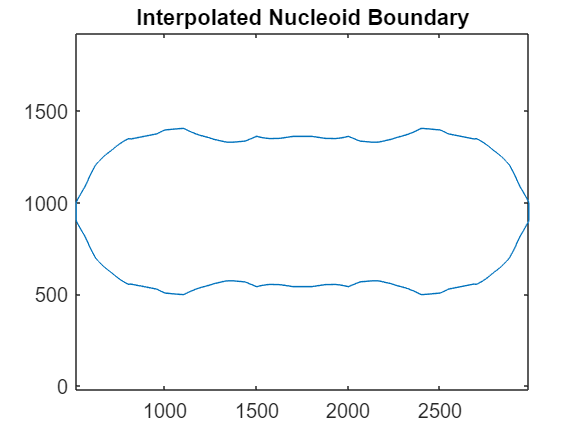

yv = (1:1/intp_rate:1/gap_y);
xv = (1:1/intp_rate:1/gap_y*aspt_ratio);
[Xv,Yv] = meshgrid(xv,yv);
intep_map = interp2(X,Y,test.',Xv,Yv);
intep_map = intep_map.';
clear x y X Y xv yv Xv Yv

thres = max(max(intep_map))*nuc_thres;
sel_ind = intep_map>thres;
see2 = intep_map;
see2(sel_ind) = 0;

[ind1, ind2] = find(intep_map>thres);
ind = cat(2,ind1,ind2);
nuc_bndy = boundary(ind(:,1),ind(:,2));
nuc_bndy = ind(nuc_bndy,:);
figure
plot(nuc_bndy(:,1),nuc_bndy(:,2))
axis equal
title('Interpolated Nucleoid Boundary')

clear ind1 ind2

[num_l,num_s] = size(intep_map);
aa = nuc_bndy(:,2)/num_s-1/num_s-0.5+0.5*gap_y/intp_rate;
bb = nuc_bndy(:,1)/num_l-1/num_l-0.5+0.5*gap_x/intp_rate;
cc_intp = cat(2,bb,aa);
clear num_l num_s aa bb nuc_bndy
clear test see2 thres intep_map

Nanocage heat map with nucleoid boundary

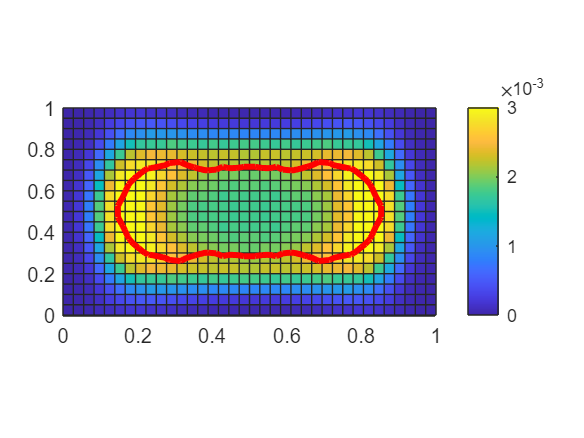

try
    for i=1:size(Result_cat)
        if Result_cat(i,1)>0
            Result_cat(i,1)=-Result_cat(i,1);
        end
        if Result_cat(i,2)>0
            Result_cat(i,2)=-Result_cat(i,2);
        end
    end
    Result_cat3=[Result_cat(:,1) -Result_cat(:,2)];
    Result_cat4=[-Result_cat(:,1) -Result_cat(:,2)];
    Result_cat5=[-Result_cat(:,1) Result_cat(:,2)];
    Result_cat_sym=[Result_cat(:,[1 2]);Result_cat3;Result_cat4;Result_cat5];
    clear Result_cat3 Result_cat4 Result_cat5 i
    nanocage_sym = Result_cat_sym;
    clear Result_cat_sym Result_cat
catch
    if exist('nanocage_sym','var') == 0
        disp('Load nanocage heat map raw data')
    end
end

figure
histogram2(nanocage_sym(:,1),nanocage_sym(:,2),'XBinEdges',-0.5:gap_x:0.5,'YBinEdges',-0.5:gap_y:0.5,...
    'Normalization','probability','DisplayStyle','tile','FaceColor','flat','ShowEmptyBins','on')
hold on
plot(cc_intp(:,1),cc_intp(:,2),'red','LineWidth',3)
% plot(cc(:,1),cc(:,2),'red','LineWidth',3)
xlim([-0.5 0.5])
xticks([-0.5  -0.3  -0.1  0.1  0.3  0.5])
ylim([-0.5 0.5])
yticks([-0.5  -0.3  -0.1  0.1  0.3  0.5])
xticklabels({'0','0.2','0.4','0.6','0.8','1'});
yticklabels({'0','0.2','0.4','0.6','0.8','1'})
pbaspect([aspt_ratio 1 1])
set(gca,'CLim',[0,3e-3])
colorbar

clear test

% heat map of nanocage
test = histcounts2(nanocage_sym(:,1),nanocage_sym(:,2),'XBinEdges',-0.5:gap_x:0.5,'YBinEdges',-0.5:gap_y:0.5);
test=test/(sum(sum(test)));
nonZeroIndices = see ~= 0;
Excluded_Fraction = sum(test(nonZeroIndices));
clear test thres nonZeroIndices

disp('Lower Bound of Exclusion Fraction')

Lower Bound of Exclusion Fraction


Exclusion_0

Exclusion_0 = 0.5263

disp('Upper Bound of Exclusion Fraction')

Upper Bound of Exclusion Fraction


Exclusion_all

Exclusion_all = 0.6478

disp('Exclusion Fraction of this condition')

Exclusion Fraction of this condition


Excluded_Fraction

Excluded_Fraction = 0.5876

% 2*Excluded_Fraction/Exclusion_all-1
if Excluded_Fraction>= Exclusion_0
    Norm_Exclusion = (Excluded_Fraction-Exclusion_0)/(Exclusion_all-Exclusion_0);
else
    Norm_Exclusion = Excluded_Fraction/Exclusion_0-1;
end
disp('Normalized Exclusion Fraction of this condition')

Normalized Exclusion Fraction of this condition


Norm_Exclusion

Norm_Exclusion = 0.5043

disp('-----------------------------------------')

-----------------------------------------


Random subsampling 

Num_group = 5;
pixel_size=49;
low_bd = 1.5;
up_bd = 4;
Rep_EF = zeros(Num_group,1);
Rep_norm_EF = zeros(Num_group,1);

Filefolder=uigetdir('L:\MIGRATED\Lab_Members\Xiaofeng_Dai\2025Winter\WT_96h_nanocage_Combine', 'Select the Folder Containing Nanocage Fits and Phasemasks');
Fitsname=uigetfile([Filefolder,filesep,'*fits.mat'],'MultiSelect','on');
Maskname=uigetfile([Filefolder,filesep,'*PhaseMask.mat'],'MultiSelect',"on");
Num_file=length(Fitsname);

Store_Mask=cell(Num_file,1);
Store_tracks=cell(Num_file,1);
parfor i=1:Num_file
    fitsname=Fitsname{i};
    fitspath=[Filefolder,filesep,fitsname];
    track = load(fitspath,'tracks');
    Store_tracks{i} = track.tracks;
    maskname=Maskname{i};
    maskpath=[Filefolder,filesep,maskname];
    mask = load(maskpath);
    Store_Mask{i} = mask.PhaseMask;
end
clear Fitsname Maskname
All_Mask = Store_Mask;
All_tracks = Store_tracks;
clear Store_tracks Store_Mask

file_ind = randperm(Num_file);
for iii =1:Num_group
    if iii<Num_group
        sel_ind = file_ind((iii-1)*floor(Num_file/Num_group)+1:...
            iii*floor(Num_file/Num_group));
    else
        sel_ind = file_ind((iii-1)*floor(Num_file/Num_group)+1:end);
    end
    Store_Mask = All_Mask(sel_ind);
    Store_tracks = All_tracks(sel_ind);
    
    num_roi=length(sel_ind);
    Result_Filter=cell(num_roi,1);
    parfor i=1:num_roi
        mask=Store_Mask{i};
        num_cell=max(mask,[],"all");
        result=zeros(num_cell,5);
        result(:,1)=(1:1:num_cell);
        roi_size=size(mask);
        for j=1:num_cell
            singlecell=mask;
            singlecell(singlecell~=j)=0;
            [ind1, ind2]=find(singlecell==j);
            if isempty(ind1)
                continue
            end
            r_up=min(ind1);
            r_up=max(1,r_up-10);
            r_down=max(ind1);
            r_down=min(r_down+10,roi_size(1));
            col_left=min(ind2);
            col_left=max(1,col_left-10);
            col_right=max(ind2);
            col_right=min(roi_size(2),col_right+10);
            singlecell=singlecell(r_up:r_down,col_left:col_right);
            singlecell=singlecell/j;
            ImgProp = regionprops('table',singlecell,'PixelList');
            FeretAna = feretProperties(ImgProp);
            Longaxis=FeretAna.MaxFeretDiameter;
            Shortaxis=FeretAna.MinFeretDiameter;
            aspt_ratio=Longaxis/Shortaxis;
            result(j,2)=Longaxis*pixel_size/1000;            %length of long axis in um
            result(j,3)=Shortaxis*pixel_size/1000;           %length of short axis in nm
            result(j,4)=aspt_ratio;                          %aspect ratio
            result(j,5)=length(ind1)*(pixel_size^2)/1e6;     % size of each cell in um^2
        end
        Result_Filter{i}=result;
    end
    
    clear col_left col_right r_up r_down Longaxis
    clear FeretAna i j ImgProp ind1 ind2 Lon Shortaxis aspt_ratio num_cell
    clear result roi_size singlecell mask  num_roi
%     Result_cat=cat(1,Result_Filter{:});
%     Result_cat=Result_cat(Result_cat(:,2)~=0,:);
    
    Index = cell(length(sel_ind),1);
    for i=1:length(sel_ind)
        cell_len = Result_Filter{i};
        test1 = cell_len(:,2)<up_bd;
        test2 = cell_len(:,2)>low_bd;
        test = test1+test2;
        ind = test==2;
        index = cell_len(ind,1);
        Index{i}=index;
    end
    clear i cell_len test1 test2 test ind index

    Result_all=cell(length(sel_ind),1);
    for i=1:length(sel_ind)
        tracks = Store_tracks{i};
        PhaseMask = Store_Mask{i};
        index = Index{i};
        
        Numcell=length(index);
        MaskStore=cell(Numcell,1);
        if isempty(tracks)==0
            for iw=1:Numcell
                ind = index(iw);
                SingleCell=PhaseMask;
                SingleCell(SingleCell~=ind)=0;
                MaskStore{iw}=SingleCell;
                
            end
            TrackStore=cell(Numcell,1);
            for ia=1:Numcell
                ind = index(ia);
                loc_index=tracks(:,5)==ind;
                TrackStore{ia}=tracks(loc_index,2:3);
            end
        end
        
        Result_Singlecell=cell(Numcell,1);
        try
            for ik=1:Numcell
                if isempty(TrackStore{ik})==0
                    ImgProp = regionprops('table',MaskStore{ik},'PixelList');
                    FeretAna = feretProperties(ImgProp);
                    %%%
                    test=FeretAna;
                    deter=test.PixelList;
                    buff=zeros(length(deter));
                    for w=1:length(deter)
                        if isempty(deter{w})==0
                            buff(w)=1;
                        end
                    end
                    FeretAna=test(buff==1,:);
                    clear test deter buff w 
                    %%%
                    PoleAxis = cell2mat(FeretAna.MaxFeretDiameterEndpoints); %FeretAna.MaxFeretDiameterEndpoints
                    center = cell2mat(FeretAna.MinAreaBoundingBox);
                    center = (center(1,:)+center(3,:))/2;
                    Xlength = FeretAna.MaxFeretDiameter;
                    if FeretAna.MaxFeretDiameterOrientation>0
                        PoleAngleX=180-FeretAna.MaxFeretDiameterOrientation;
                        PoleAngleX=(PoleAngleX*pi)/180;
                    elseif FeretAna.MaxFeretDiameterOrientation<=0
                        PoleAngleX=-(pi*FeretAna.MaxFeretDiameterOrientation)/180;
                    end
                    Ylength=FeretAna.MinFeretDiameter;
                    if FeretAna.MinFeretDiameterOrientation>0
                        PoleAngleY=180-FeretAna.MinFeretDiameterOrientation;
                        PoleAngleY=(PoleAngleY*pi)/180;
                    elseif FeretAna.MinFeretDiameterOrientation<=0
                        PoleAngleY=-(pi*FeretAna.MinFeretDiameterOrientation)/180;
                    end
                    tmpstore=TrackStore{ik};
                    tmp5=size(tmpstore);
                    tmp5=tmp5(1);
                    vecter=zeros(tmp5,8);
                    % vecter col#1&col#2 vecter(x,y) connecting each point and center
                    % vecter col#3 real distance between point and center
                    % vecter col#4 angle between vecter(x,y) and xaxis (1,0)
                    % vecter col#5 vecter(x,y) angle to PoleAngleX
                    % vecter col#6 vecter(x,y) angle to PoleAngleY
                    % vecter col#7&col#8 normalized coordinate
                    vecter(:,1)=tmpstore(:,2)-center(1);
                    vecter(:,2)=-tmpstore(:,1)+center(2);
                    vecstd=[1,0];
                
                    for ii=1:tmp5
                        vecter(ii,4)=anglevec(vecstd,[vecter(ii,1),vecter(ii,2)]);
                    end
                    clear ii
                    vecter(:,3)=sqrt(vecter(:,1).^2+vecter(:,2).^2);
                    for ii=1:tmp5
                        thetaX=PoleAngleX-vecter(ii,4);
                        if (thetaX<=-pi) && (thetaX>-2*pi)
                            vecter(ii,5)=mod(thetaX,pi);
                        else
                            vecter(ii,5)=thetaX;
                        end
                    end
                    clear ii
                    for ii=1:tmp5
                        thetaY=PoleAngleY-vecter(ii,4);
                        if (thetaY<=-pi) && (thetaY>-2*pi)
                            vecter(ii,6)=mod(thetaY,pi);
                        else
                            vecter(ii,6)=thetaY;
                        end
                    end
                    clear ii
                    angleref=abs(PoleAngleX-PoleAngleY);
                    vecter(:,7)=(vecter(:,3)/sin(angleref)).*sin(vecter(:,6));
                    vecter(:,8)=(vecter(:,3)/sin(angleref)).*sin(vecter(:,5));
                    vecter(:,7)=vecter(:,7)/Xlength;
                    vecter(:,8)=vecter(:,8)/Ylength;
                    
                    store=zeros(tmp5,3);
                    store(:,1)=vecter(:,7);
                    store(:,2)=vecter(:,8);
                    Result_Singlecell{ik}=store;
                
                end
                
            end
        catch
        end
        clear store
        for il=1:Numcell
            tmp7=isempty(Result_Singlecell{il,1});
            if tmp7==0
                store=Result_Singlecell{il,1};
                len_all=size(store);
                len_all=len_all(1);
                indct1=find(abs(store(:,1))>0.5);
                len1=size(indct1);
                indct2=find(abs(store(:,2))>0.5);
                len2=size(indct2);
                len_err=len1+len2;
                len_err=len_err(1);
                if isempty(indct1) && isempty(indct2)
                    Result_Singlecell{il,1}=store;
                elseif len_err<0.05*len_all
                    indct=cat(1,indct1,indct2);
                    clear index
                    index=unique(indct);
                    store(index,:)=[];
                    Result_Singlecell{il,1}=store;
                elseif len_err>=0.05*len_all
                    Result_Singlecell{il,1}=[];
                end
                
            end
            Result_File=cat(1,Result_Singlecell{:});
            Result_all{i}=Result_File;
        end
        
    end

    Result_cat=cat(1,Result_all{:});

    for i=1:size(Result_cat)
        if Result_cat(i,1)>0
            Result_cat(i,1)=-Result_cat(i,1);
        end
        if Result_cat(i,2)>0
            Result_cat(i,2)=-Result_cat(i,2);
        end
    end
    Result_cat3=[Result_cat(:,1) -Result_cat(:,2)];
    Result_cat4=[-Result_cat(:,1) -Result_cat(:,2)];
    Result_cat5=[-Result_cat(:,1) Result_cat(:,2)];
    Result_cat_sym=[Result_cat(:,[1 2]);Result_cat3;Result_cat4;Result_cat5];

    test = histcounts2(Result_cat_sym(:,1),Result_cat_sym(:,2),'XBinEdges',-0.5:gap_x:0.5,'YBinEdges',-0.5:gap_y:0.5);
    test=test/(sum(sum(test)));
    nonZeroIndices = see ~= 0;
    Excluded_Fraction = sum(test(nonZeroIndices));
    
    fprintf('From Round %d', iii)
    disp('Exclusion Fraction of this condition')
    Excluded_Fraction
    
    if Excluded_Fraction>= Exclusion_0
        Norm_Exclusion = (Excluded_Fraction-Exclusion_0)/(Exclusion_all-Exclusion_0);
    else
        Norm_Exclusion = Excluded_Fraction/Exclusion_0-1;
    end
    disp('Normalized Exclusion Fraction of this condition')
    Norm_Exclusion
    disp('-----------------------------------------')
    Rep_EF(iii) = Excluded_Fraction;
    Rep_norm_EF(iii) = Norm_Exclusion;
end

From Round 1

Exclusion Fraction of this condition


Excluded_Fraction = 0.5786

Normalized Exclusion Fraction of this condition


Norm_Exclusion = 0.4302

-----------------------------------------


From Round 2

Exclusion Fraction of this condition


Excluded_Fraction = 0.5978

Normalized Exclusion Fraction of this condition


Norm_Exclusion = 0.5882

-----------------------------------------


From Round 3

Exclusion Fraction of this condition


Excluded_Fraction = 0.5947

Normalized Exclusion Fraction of this condition


Norm_Exclusion = 0.5627

-----------------------------------------


From Round 4

Exclusion Fraction of this condition


Excluded_Fraction = 0.5790

Normalized Exclusion Fraction of this condition


Norm_Exclusion = 0.4340

-----------------------------------------


From Round 5

Exclusion Fraction of this condition


Excluded_Fraction = 0.5832

Normalized Exclusion Fraction of this condition


Norm_Exclusion = 0.4686

-----------------------------------------


clearvars -except cc cc_intp coord_nuc Exclusion_0 ...
    Exclusion_all gap_x gap_y Hu_sym intp_rate low_bd nanocage_sym ...
    nuc_thres Num_group Rep_EF Rep_norm_EF up_bd Vol_cell Vol_nuc ...
    Vol_project aspt_ratio